clc;
clear;

## ب : رسم نمودار میانگین فرآیند تصادفی 

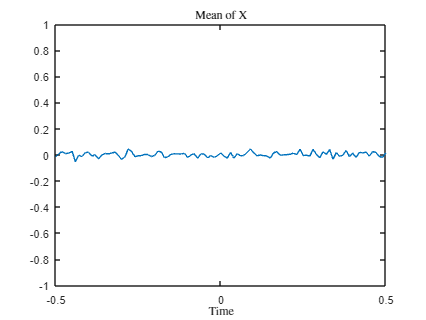

fs = 100;
t = -0.5 : 1/fs :0.5;
N = 10^5;
A = 10;
w0 = 5*pi;
theta = 2*pi*rand(N,length(t));
X = A.*cos(w0.*t + theta);
plot(t,mean(X))
ylim ([-1 1])
xlabel('Time','Interpreter','latex');
title('Mean of X','Interpreter','latex');

## پ : رسم نمودار خودهمبستگی فرآیند تصادفی

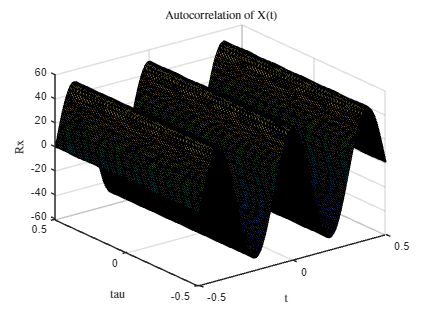

tau = -0.5:1/fs:0.5;
R = ones(length(t),length(tau));
for i =1:length(t)
     R(i,:) = mean(A.*cos(w0.*(t(1,i)+tau)+theta).* A.*cos(w0.*t(1,i)+theta));
end
surf(t,tau,R)
title('Autocorrelation of X(t)', 'Interpreter','latex')
xlabel('t','Interpreter','latex')
ylabel('tau','Interpreter','latex')
zlabel('Rx','Interpreter','latex')

## ت : مقایسه با محاسبات تئوری

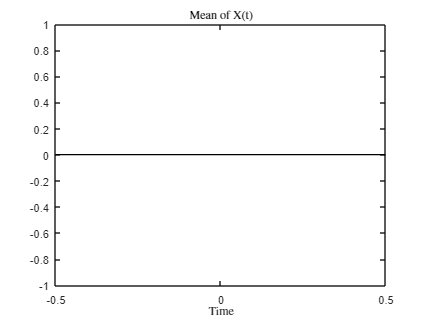

% plotting mean of X base on theoretical calculations
E = zeros(1,length(t));
plot(t,E,'k')
title('Mean of X(t)','Interpreter','latex')
xlabel('Time','Interpreter','latex')

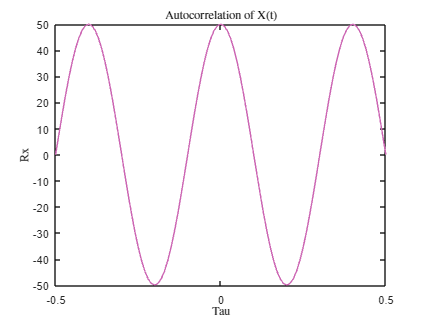


% plotting autocorrelation of X based on theoretical calculations
Rx = A^2/2.*cos(w0.*tau);
plot(tau, Rx,'Color', [0.8 0.4 0.7])
title('Autocorrelation of X(t)','Interpreter','latex')
xlabel('Tau','Interpreter','latex')
ylabel('Rx','Interpreter','latex')

## ث: ایستان سازی فرآیند

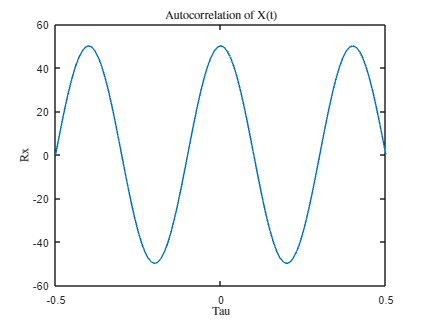

plot(tau,mean(R))
title('Autocorrelation of X(t)','Interpreter','latex')
xlabel('Tau','Interpreter','latex')
ylabel('Rx','Interpreter','latex')